# 7.5 频率采样法设计 FIR：按线性相位约束给 H(k)，IDFT 得 h(n)；过渡带加采样点把阻带从 −20 dB 压到 −60 dB（教材例 7.17—7.20）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if isempty(here), here = pwd; end
outdir = fullfile(here, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：例 7.17：N=33，ωc=0.5π，|H(k)|=1（k=0…8 及对称的 25…32），相位按式 (7.3.20)：θ(k)=−πk(N−1)/N

w = linspace(0, pi, 8192);
[hA, HkA, magA] = fs_design_type1(33, 0.5*pi, []);
HA = polyval(fliplr(hA), exp(-1i*w)); magHA = abs(HA);
wk = 2*pi*(0:32)/33; Hsamp = abs(polyval(fliplr(hA), exp(-1i*wk)));            % 采样点上应恰好等于 |H(k)|
errSamp = max(abs(Hsamp - magA));
symErr = max(abs(hA - fliplr(hA)));                                              % h(n) 应对称（1 型）
[attA, wsA] = stop_att(magHA, w, 33, 8);                                         % 最后一个非零样本 k=8，阻带从 k=10 起

## 演示2：例 7.19：加一个过渡带采样 `H(9)`=|H(24)|=0.5

[hB, HkB, magB] = fs_design_type1(33, 0.5*pi, 0.5);
HB = polyval(fliplr(hB), exp(-1i*w)); [attB, wsB] = stop_att(abs(HB), w, 33, 9);
% 0.5 只是个起点：扫描过渡采样值 T1，找阻带衰减最大的（教材 7.3.3 所说的“优化过渡带采样”）
T1s = 0.20:0.005:0.60; attScan = zeros(size(T1s));
for i = 1:numel(T1s), hb = fs_design_type1(33, 0.5*pi, T1s(i)); attScan(i) = stop_att(abs(polyval(fliplr(hb), exp(-1i*w))), w, 33, 9); end
[attBopt, iOpt] = max(attScan); T1opt = T1s(iOpt); hBopt = fs_design_type1(33, 0.5*pi, T1opt); HBopt = polyval(fliplr(hBopt), exp(-1i*w));

## 演示3：例 7.20：N=65，两个过渡带采样 `H(17)`=0.5886，|H(18)|=0.1065（教材给出的优化值）

[hC, HkC, magC] = fs_design_type1(65, 0.5*pi, [0.5886 0.1065]);
HC = polyval(fliplr(hC), exp(-1i*w)); [attC, wsC] = stop_att(abs(HC), w, 65, 18);

## 演示4：核验内插公式（教材式 (7.3.3)(7.3.4)）：H(z)=(1−z^{−N})/N · Σ H(k)/(1−W_N^{−k}z^{−1}) 与 DTFT 逐点一致；与汉明窗 N=33 比较

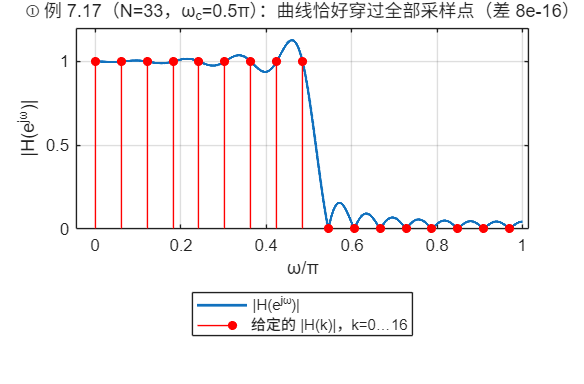

wi = w(40:end); z = exp(1i*wi); Hint = zeros(size(wi)); N = 33;                % ω=0 附近 0/0 病态，从 ω>0.015 起核验
for k = 0:N-1, Hint = Hint + HkA(k+1)./(1 - exp(2i*pi*k/N)*z.^-1); end
Hint = (1 - z.^-N)/N.*Hint; errInterp = max(abs(Hint - HA(40:end)));
n = 0:32; alpha = 16; hdW = sin(0.5*pi*(n - alpha))./(pi*(n - alpha)); hdW(alpha+1) = 0.5;
hHam = hdW.*(0.54 - 0.46*cos(2*pi*n/32)); HHam = abs(polyval(fliplr(hHam), exp(-1i*w)));
attHam = -20*log10(max(HHam(w > 0.62*pi)));

if ~LIVE, f1 = figure('Name','05 频率采样法','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(w/pi, magHA, 'LineWidth', 1.6); hold on; stem(wk(1:17)/pi, magA(1:17), 'r', 'filled', 'MarkerSize', 5);
grid on; xlabel('ω/π'); ylabel('|H(e^{jω})|');
title(sprintf('① 例 7.17（N=33，ω_c=0.5π）：曲线恰好穿过全部采样点（差 %.0e）', errSamp));
legend('|H(e^{jω})|', '给定的 |H(k)|，k=0…16');

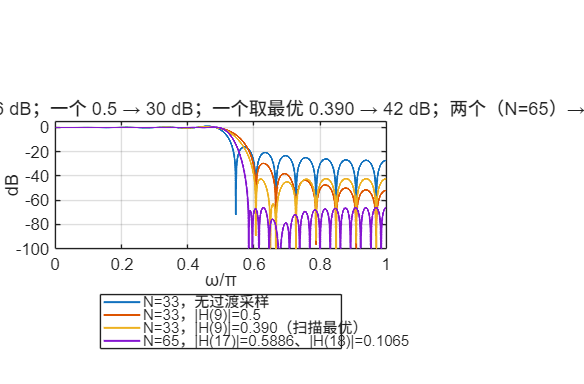

newpanel(); plot(w/pi, 20*log10(magHA), 'LineWidth', 1.2); hold on; plot(w/pi, 20*log10(abs(HB)), 'LineWidth', 1.2); plot(w/pi, 20*log10(abs(HBopt)), 'LineWidth', 1.2); plot(w/pi, 20*log10(abs(HC)), 'LineWidth', 1.2);
grid on; ylim([-100 5]); xlabel('ω/π'); ylabel('dB');
title(sprintf('② 过渡带采样：无 → %.0f dB；一个 0.5 → %.0f dB；一个取最优 %.3f → %.0f dB；两个（N=65）→ %.0f dB', attA, attB, T1opt, attBopt, attC));
legend('N=33，无过渡采样', 'N=33，|H(9)|=0.5', sprintf('N=33，|H(9)|=%.3f（扫描最优）', T1opt), 'N=65，|H(17)|=0.5886、|H(18)|=0.1065');

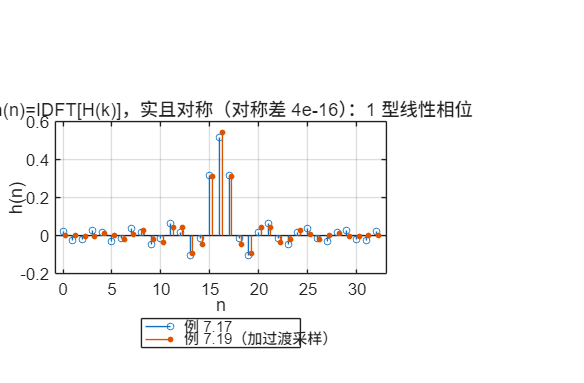

newpanel(); stem(0:32, hA, 'MarkerSize', 4); hold on; stem((0:32)+0.25, hB, 'filled', 'MarkerSize', 3);
grid on; xlabel('n'); ylabel('h(n)'); title(sprintf('③ h(n)=IDFT[H(k)]，实且对称（对称差 %.0e）：1 型线性相位', symErr));
legend('例 7.17', '例 7.19（加过渡采样）');

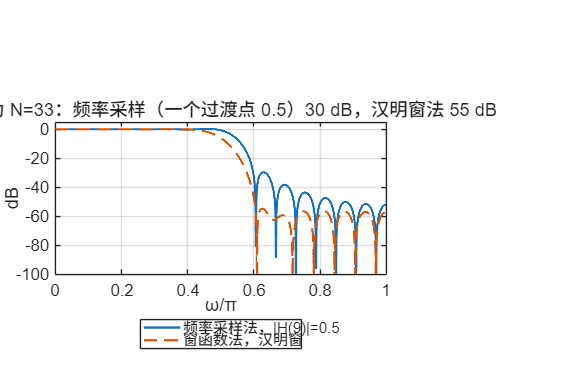

newpanel(); plot(w/pi, 20*log10(abs(HB)), 'LineWidth', 1.4); hold on; plot(w/pi, 20*log10(HHam), '--', 'LineWidth', 1.4);
grid on; ylim([-100 5]); xlabel('ω/π'); ylabel('dB');
title(sprintf('④ 同为 N=33：频率采样（一个过渡点 0.5）%.0f dB，汉明窗法 %.0f dB', attB, attHam));
legend('频率采样法，|H(9)|=0.5', '窗函数法，汉明窗');

if ~LIVE, sgtitle('频率采样法：在 N 个频点上“钉住”H(k)，点之间由内插公式决定；过渡带留 1—2 个可调采样点，阻带大幅改善'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '05-frequency-sampling-design.png'), 'Resolution', 150); end

## 教师核验

assert(errSamp < 1e-10 && symErr < 1e-12 && errInterp < 1e-8, '采样点/对称性/内插公式核验失败');
assert(attA > 15 && attA < 25, '无过渡采样的阻带应约 20 dB');
assert(attB > attA + 10 && attBopt > attB + 5 && attC > attBopt + 10, '过渡带采样应显著改善阻带');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'ex717_N', 33, 'ex717_Hk_mag', magA, 'ex717_err_samples', errSamp, 'ex717_h_sym_err', symErr, 'ex717_stop_att_dB', attA, 'ex717_stop_start_over_pi', wsA/pi, ...
    'ex719_stop_att_dB', attB, 'ex719_T1_opt', T1opt, 'ex719_stop_att_dB_opt', attBopt, 'ex720_N', 65, 'ex720_stop_att_dB', attC, 'interp_formula_err', errInterp, 'hamming_N33_stop_att_dB', attHam, ...
    'h_ex717', hA, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-frequency-sampling-design.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

              matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                      run_at: '2026-09-18 22:16:13'
                     ex717_N: 33
                ex717_Hk_mag: [1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1]
           ex717_err_samples: 7.7716e-16
             ex717_h_sym_err: 3.8858e-16
           ex717_stop_att_dB: 16.1278
    ex717_stop_start_over_pi: 0.5455
           ex719_stop_att_dB: 29.6365
                ex719_T1_opt: 0.3900
       ex719_stop_att_dB_opt: 42.2332
                     ex720_N: 65
           ex720_stop_att_dB: 66.1428
          interp_formula_err: 2.7385e-12
     hamming_N33_stop_att_dB: 54.6137
                     h_ex717: [0.0209 -0.0231 -0.0193 0.0261 0.0180 -0.0303 -0.0170 0.0365 0.0163 -0.0463 -0.0158 0.0643 0.0154 -0.1065 -0.0152 0.3184 0.5152 0.3184 -0.0152 -0.1065 0.0154 0.0643 -0.0158 -0.0463 0.0163 0.0365 -0.0170 … ] (1×33 double)
           all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Te

## 本地函数

function [h, Hk, mag] = fs_design_type1(N, wc, trans)
% 1 型（N 奇、h 对称）频率采样设计：|H(k)| 在通带为 1，过渡带取给定值，其余 0；相位 θ(k) 按教材式 (7.3.20)
k = 0:N-1; kc = floor(N*wc/(2*pi));                    % 最后一个通带样本
mag = zeros(1, N); mag(k <= kc) = 1;
for i = 1:numel(trans), mag(kc + i + 1) = trans(i); end
mag = max(mag, [mag(1) fliplr(mag(2:end))]);          % |H(N−k)|=|H(k)|：下标 j 的配对是 N−j+2
theta = zeros(1, N); L = (N - 1)/2;
theta(k <= L) = -pi*k(k <= L)*(N - 1)/N; theta(k > L) = pi*(N - k(k > L))*(N - 1)/N;
Hk = mag.*exp(1i*theta);
h = real(ifft(Hk));
end

function [att, ws] = stop_att(Hmag, w, N, kLast)
% 阻带从最后一个非零样本之后的下一个样本频率算起
ws = 2*pi*(kLast + 1)/N; att = -20*log10(max(Hmag(w >= ws)));
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end